# Demostración General de la Herramienta

# Uso de las App

Dificultad: Normal (Ejemplo anteriores con App)

## Iconos de la Librería SimRobot

- Se dispone de clases de iconos para crear estaciones, los iconos de trabajo, los de robot y otros elementos.

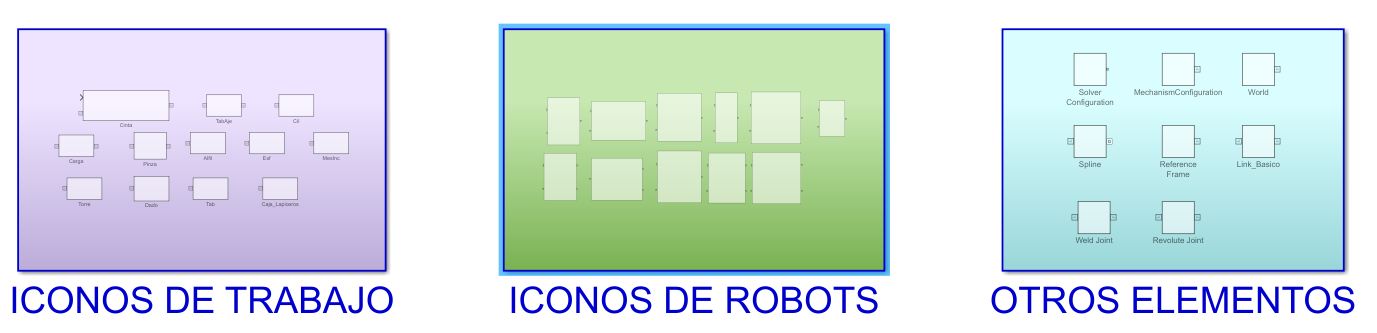

### Iconos de trabajo

- Son los iconos de las piezas estáticas que van a ser usadas en las estaciones

- Hay iconos constantes, ya que el elemento asociado no cambia, solo su posición dentro de sistema. Dentro de nuestro modelo el tablero de ajedrez es el único que debe ser constante por tener dos ficheros stl asociados. Los demás elementos pueden ser variables o constantes, por ejemplo, el cilindro y la esfera.

- Hay iconos variables, ya que el elemento asociado cambia de figura y propiedades mecánicas. La  Carga y Pinza deben ser variables, y los demás elementos pueden serlo también.

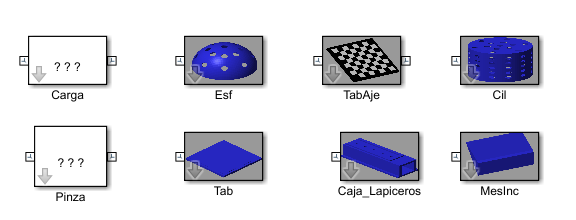

### Iconos de robots

- Se dispone de diferentes modelos de robot obtenidos de la conversión de los modelos de robot en formato URDF (Universal Robot Defined Format) a formato SimScape.

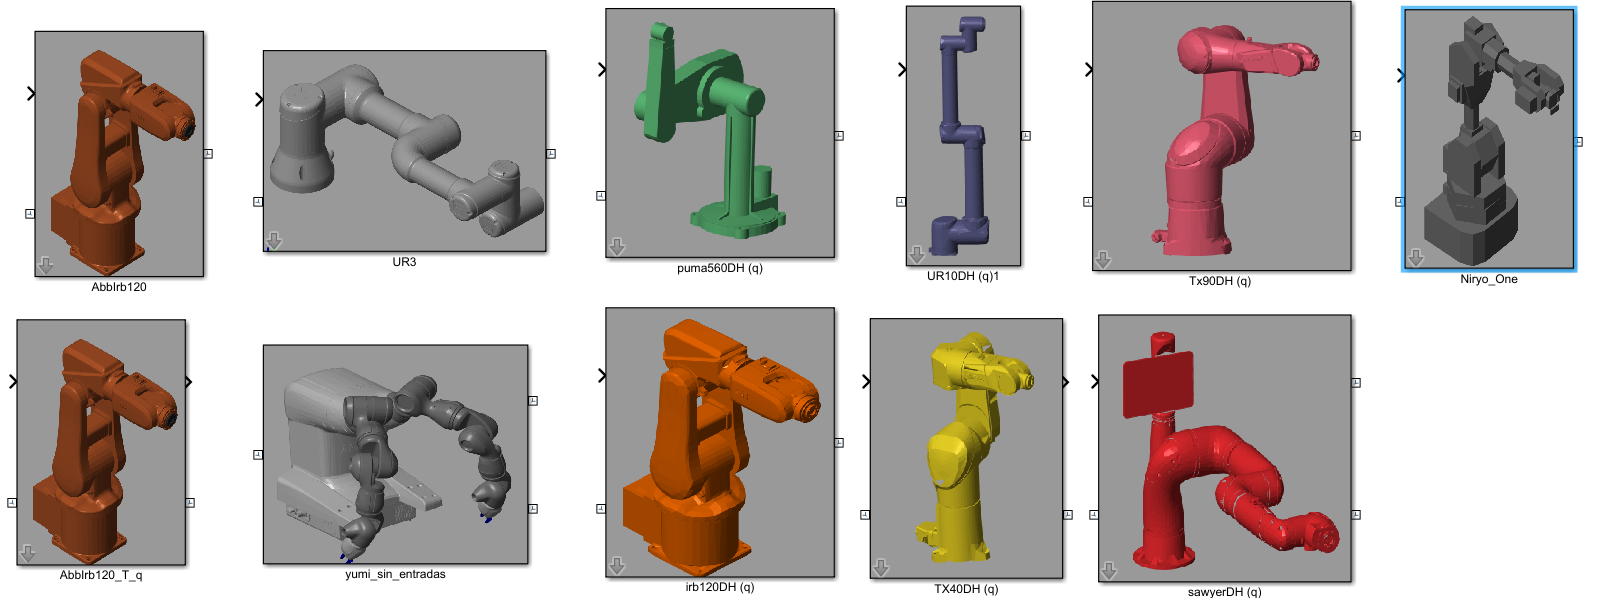

### Iconos de control

- Elementos de la librería SimScape que son usados.

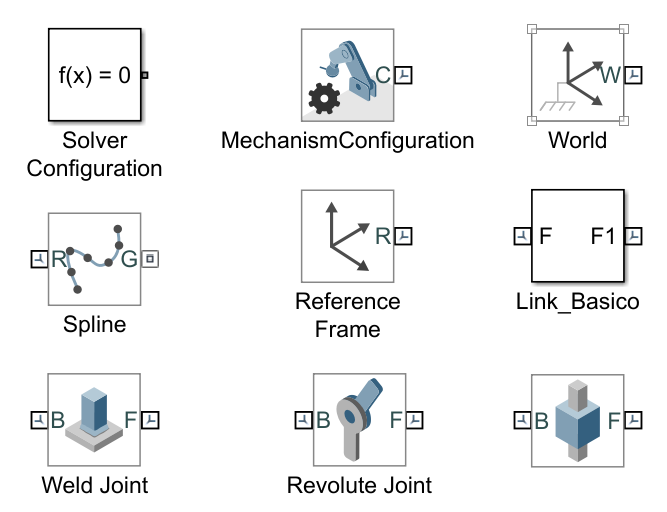

## Introducción

- El objetivo de la clase $Kin()$ es poder realizar un simulador de robot usando las herramientas **Multi-Body** de Simulink y **Rigid-Body** de Matlab. 

- Los métodos principales de la clase **Cin** son los movimientos típicos de todo lenguaje para programación de robot: $MoveAbsJ()$ (movimiento por coordenadas articulares), $MoveJ()$ (movimientos por coordenadas cartesianas), $MoveL()$ (movimiento en linea) y $MoveC()$ (movimiento en arco).

- Se parte de un modelo de robot definido en **Multi-Body** y su equivalente en **Rigid-Body** definido a partir del primero.

- A ambos modelos se les pueden añadir todo tipo de herramientas y objetos de trabajo. Sin embargo, la simulación de movimientos es más continua en Simulink, por lo que se va a usar básicamente **Multi-Body** para la simulación. 

- En este entorno se puede definir la velocidad de simulación y se va a poder grabar los movimientos realizados para posteriormente reproducirlos.

- El modelo equivalente de **Rigid-Body** es necesario para poder obtener las cinemáticas inversas y directas del modelo, ya que **Multi-Body** solo simula.

- Se ha diseñado un **HMI** (interface hombre-máquina) **appRastreador** basado en la herramienta **appdesigner** de matlab, que usando la clase **Cin**, mueve al robot en coordenadas cartesianas.

## Abrir clase Cin para Rigid-Body y Multi-Body

- Si se introducen como argumentos el objeto **Rigid-Body** y el fichero Simulink de **Multi-Body**, las salidas por pantalla se convierten en simulaciones a la velocidad deseada.

- El objeto **Rigid-Body** puede constar solo del robot, ya que no se va a visualizar, solo se va a usar para la obtención de la cinemática directa e inversa.

- En el fichero **Multi-Body** se pueden añadir las herramientas que se deseen y los objetos de trabajo.

### Limpieza y definición de funciones anónimas de interes

- Conversión entre metros y milimetros, radianes y grados.

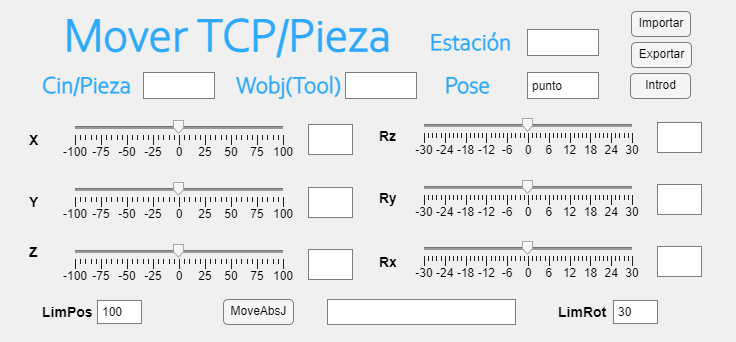

clear all
close all

deg= pi/180;


### Aplicación appMover

#### Movimiento de piezas

- Se debe indicar el nombre de la variable donde está definida la pieza y la estación Simulink.

- La base de la pieza se mueve de forma relativa a la posición actual respecto a las coordenadas de Euler $[[x,y,z]mm,[R_z,R_y,R_x]deg]$.

#### Movimientos de un robot

- Se debe dar el nombre de la variable donde está definida el objeto Cin del robot.

- Cinemática directa $MoveAbsJ$: Se mueven las articulaciones a los ángulos que se marquen

- Cinemática inversa: Movimiento lineal relativo a la posición dada con las coordenadas de Euler $[[x,y,z]mm,[R_z,R_y,R_x]deg]$.

- Cinemática inversa respecto de referencia $Hwobj$*:* Movimiento lineal relativo respecto a la matriz homogénea $Hwobj$.

- Cinemática inversa respecto de referencia *Tool:* Movimiento lineal relativo respecto a la herramienta del robot. Ésta cambia con el movimiento del mismo.

appMover

### Estación con robot ABB120 y diferentes piezas

- Robot de ABB pequeño no colaborativo.

deg= pi/180;
Estacion= 'C09S1_Estacion_irb120';

% Se inicia la clase con el robot con el interface de simulink
% VER VERSIÓN SIMULINK
% Variables de simulink

% Posición inicial del robot y del rastreador
% Estas variables van a ser usadas por los objetos Cin como variables del sistema 
% No deben modificarse en el programa 
q0_= zeros(1,6);
pose_= randn(3,3)*1e-3;

% Posición de la base del robot [[x,y,z]mm,[Rz,Ry,Rx]rad]
baseRobot= [[0,0,0]*1e-3, [0,0,0]*deg];

% Tool load y wobj Se genera una variable estructura de nombre tool1

% Herramienta/carga del robot
Pinza= Pieza('Pinza_Completa');
Pinza.Base([[0,0,0]*1e-3, [90,0,0]*deg]);
Pinza.Tcp([[0,0,70]*1e-3, [0,0,0]*deg]);
Pinza.Color([0.4,0,0.4,0.7]);

% Herramienta/Carga del robot
Carga= Pieza('Lapiz');
Carga.Tcp([[0,0,148]*1e-3, [0,0,0]*deg]);
Carga.Color([0,0.4,0.4,0.7]);

% Objeto de trabajo del robot
Esf= Pieza('Esfera');
Esf.Base([[0,-350,0]*1e-3, [0,0,0]*deg]);
Esf.Color([0,0.3,0.8,0.7]);

% Objeto de trabajo
Tab= Pieza('Tablero');
Tab.Base([[0, 200, 100]*1e-3, [0, 0, 30]*deg]);
Tab.Color([0.2, 0.5, 0.1, 0.7])

% Icono fijo
% Mesa inclinada. Sus puntos están en una posición indeterminada respecto
% del origen. Es preciso usar la regla de los tres puntos para fijarlos
MesInc= Pieza('MesaInclinada');
MesInc.Base([[0, 0, 0]*1e-3, [0, 0, 0]*deg]);
% Ejes de la mesa por 3 puntos
% Puntos para definir los ejes de la mesa
x1= [0.4000, 0.1330, 0];
x2= [0.1500, -0.3000, 0];
y1= [0.7232, -0.0536, 0.1000];
MesInc.Tcp(Prod(x1,x2,y1));

MesInc.Color([0.3, 0.8, 0.2, 0.7]);


% Pieza('Botella', 'Botella');
% h= Hmat;
% h.Rad;
% Hbotella= h.t([45,0,45]*1e-3)*h.Rx(-90*deg);
% Botella.Base([[0,0,0]*1e-3, [0,0,0]*deg]);
% Botella.Color([0,0.3,0.8,0.7]);


% Objeto de trabajo del robot
Cil= Pieza('Cilindro');

--------------------
Robot: (10 bodies)

 Idx     Body Name     Joint Name     Joint Type     Parent Name(Idx)   Children Name(s)
 ---     ---------     ----------     ----------     ----------------   ----------------
   1        Body01        Joint01          fixed              Base(0)   Body02(2)  
   2        Body02        Joint02       revolute            Body01(1)   Body03(3)  
   3        Body03        Joint03       revolute            Body02(2)   Body04(4)  
   4        Body04        Joint04       revolute            Body03(3)   Body05(5)  
   5        Body05        Joint05       revolute            Body04(4)   Body06(6)  
   6        Body06        Joint06       revolute            Body05(5)   Body07(7)  
   7        Body07        Joint07       revolute            Body06(6)   Body08(8)  
   8        Body08        Joint08          fixed            Body07(7)   Body09(9)  
   9        Body09        Joint09          fixed            Body08(8)   Body10(10)  
  10        Body10      

Cil.Base([[0, 300, 900]*1e-3, [0, 90, 0]*deg]);
Cil.Color([0.4,0.7,0.2,0.7]);


% Abrir fichero simulink
open_system(Estacion)

% Paso de la estación de simulink al objeto Rigid Body (Robotic Toolbox)
robot= importrobot(Estacion);
robot.showdetails
% Para recordar a que body pertenece las herramientas y cargas deseadas
% Es preciso mirarlo dentro de la estructura
TcpPinza= 'Body09';
TcpCarga= 'Body10';
% Abrir fichero simulink
open_system(Estacion)

Herramienta: Body10
Simulación. Ts= 0.100 m/s


### Diagrama Simulink Multi-Body

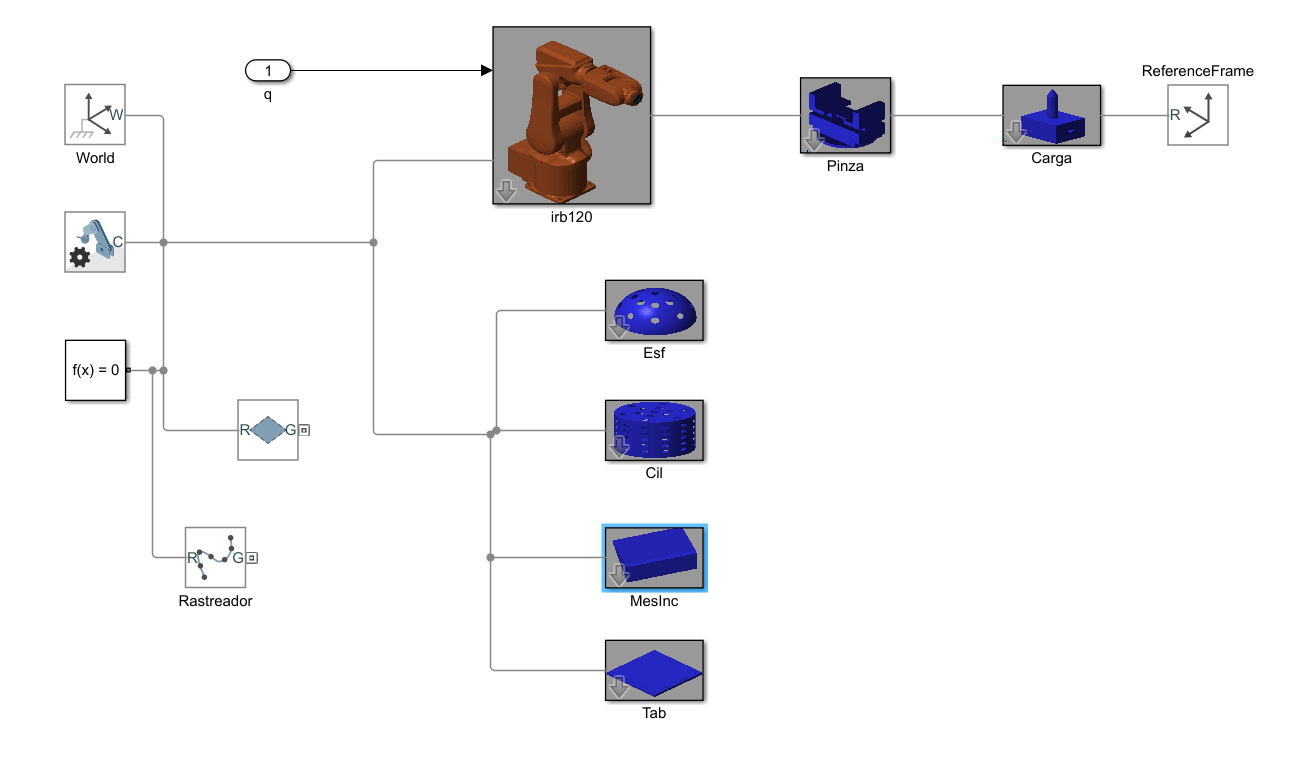

## Objeto $Cin()$ del sistema

% Se debe definir el rigid-body asociado a la estación, la estación simulink
% la herramienta deseada (última por defecto) y el valor de los ejes
% iniciales q0= [0,0,0,0,0,0] por defecto
q0= zeros(1,6);
q0_= zeros(1,6);

rob= Cin(robot, Estacion, TcpCarga, q0);
% Se va a usar el algoritmo analítico 
%rob.aik= 'irb120';

### Estación con robot colaborativo Gofa (ABB)

- Robot colaborativo de ABB con sistema operativo RobotWare 7

- Es muy flexible pero hay que marcarle bien el camino para que no vaya por uno incorrecto

deg= pi/180;
Estacion= 'C21S0_Gofa.slx';
% Se inicia la clase con el robot con el interface de simulink
% VER VERSIÓN SIMULINK
% Variables de simulink

% Posición inicial del robot y del rastreador
% Estas variables van a ser usadas por los objetos Cin como variables del sistema 
% No deben modificarse en el programa 
q0_= zeros(1,6);
pose_= randn(3,3)*1e-3;

% Posición de la base del robot
baseRobot= [[0,0,0]*1e-3, [0,0,0]*deg];
% Posición de la base del robot

% Tool load y wobj Se genera una variable estructura de nombre tool1

% Icono variable
Pinza= Pieza('Pinza_Completa');
Pinza.Base([[0,0,0]*1e-3, [0,90,0]*deg]);
Pinza.Tcp([[0,0,70]*1e-3, [0,0,0]*deg]);
Pinza.Color([0.4,0,0.4,0.7]);

% Icono variable
Carga= Pieza('Lapiz');
%Carga.Base([[0,30,150]*1e-3, [0,0,90]*deg]);
Carga.Tcp([[0,0,148]*1e-3, [0,0,0]*deg]);
Carga.Color([0,0.4,0.4,0.7]);

% Icono variable
pPunto= Pieza('Null');


% Esfera
Esf= Pieza('Esfera');
Esf.Base([[0,-350,0]*1e-3, [0,0,0]*deg]);
Esf.Color([0,0.3,0.8,0.7]);

% Mesa inclinada (icono constante)
MesInc= Pieza('MesaInclinada');
MesInc.Base([[0,0, 0]*1e-3, [0,0,0]*deg]);
% Ejes de la mesa por 3 puntos
% Puntos para definir los ejes de la mesa
x1= [0.4000, 0.1330, 0];
x2= [0.1500, -0.3000, 0];
y1= [0.7232, -0.0536, 0.1000];
MesInc.Tcp(Prod(x1,x2,y1));
MesInc.Color([0.3, 0.8, 0.2, 0.7]);

% Cilindro (icono constante)
Cil= Pieza('Cilindro');
Cil.Base([[0, 300, 900]*1e-3, [0, 90, 0]*deg]);
Cil.Color([0.4,0.7,0.2,0.7]);

% Tablero (icono constante)

--------------------
Robot: (10 bodies)

 Idx     Body Name     Joint Name     Joint Type     Parent Name(Idx)   Children Name(s)
 ---     ---------     ----------     ----------     ----------------   ----------------
   1        Body01        Joint01          fixed              Base(0)   Body02(2)  
   2        Body02        Joint02       revolute            Body01(1)   Body03(3)  
   3        Body03        Joint03       revolute            Body02(2)   Body04(4)  
   4        Body04        Joint04       revolute            Body03(3)   Body05(5)  
   5        Body05        Joint05       revolute            Body04(4)   Body06(6)  
   6        Body06        Joint06       revolute            Body05(5)   Body07(7)  
   7        Body07        Joint07       revolute            Body06(6)   Body08(8)  
   8        Body08        Joint08          fixed            Body07(7)   Body09(9)  
   9        Body09        Joint09          fixed            Body08(8)   Body10(10)  
  10        Body10      

Tab= Pieza('Tablero');
Tab.Base([[200, 200, 100]*1e-3, [0, 0, 30]*deg]);
Tab.Color([0.2,0.5,0.1,0.7])

% Abrir estación
open_system(Estacion)

% Paso de la estación de simulink al objeto Rigid Body (Robotic Toolbox)
robot= importrobot(Estacion);
robot.showdetails

Herramienta: Body10
Simulación. Ts= 0.100 m/s



TcpPinza= 'Body09';
TcpCarga= 'Body10';

% Se debe definir el rigid-body asociado a la estación, la estación simulink
% la herramienta deseada (última por defecto) y el valor de los ejes
% iniciales q0= [0,0,0,0,0,0] por defecto
q0= zeros(1,6);

rob= Cin(robot, Estacion, TcpCarga, q0);




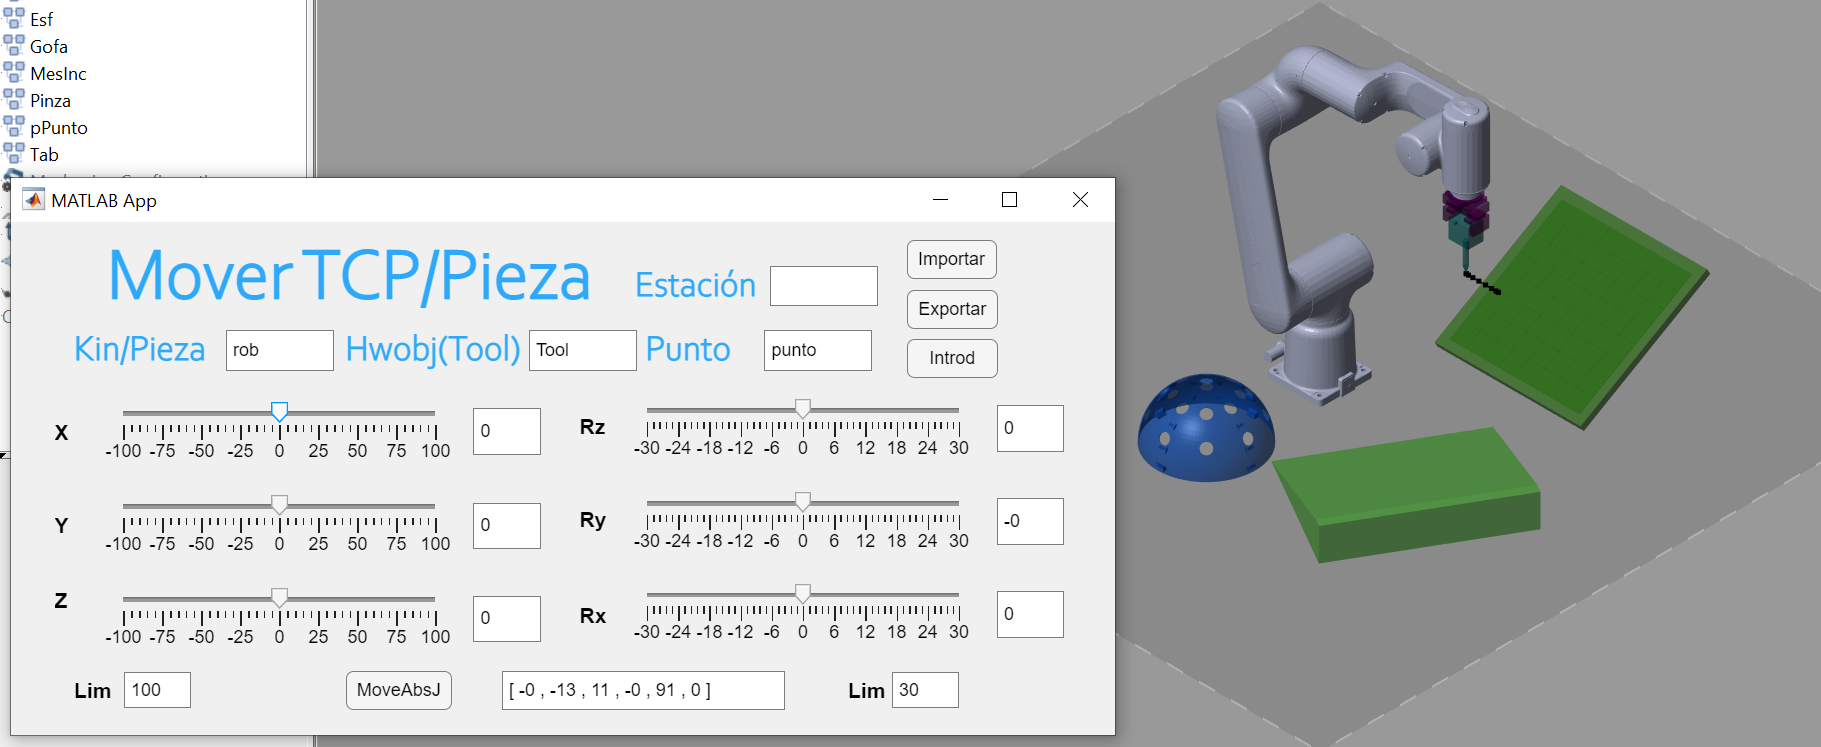

### Estacion con robot en cinta transportadora

- Estación más compleja que monta al robot ABB irb120 en una cinta transportadora.

- El robot tiene 7 grados de libertad. 

clear all
deg= pi/180;

Estacion=  'C15S2_Robot_sobre_Cinta.slx';
% Se inicia la clase con el robot con el interface de simulink
% VER VERSIÓN SIMULINK
% Variables de simulink

% Posición inicial del robot y del rastreador
% Estas variables van a ser usadas por los objetos Cin como variables del sistema 
% No deben modificarse en el programa 
q0_= zeros(1,7);
pose_= randn(3,3)*1e-3;

% Posición de la base del robot y la cinta transportadora
baseCinta= [[0,0,140]*1e-3,[0,0,0]*deg];
baseRobot= [[0,0,100]*1e-3, [0,-90,90]*deg];

% Tool load y wobj Se genera una variable estructura de nombre tool1

% Icono variable
Pinza= Pieza('Pinza_Completa');
Pinza.Base([[0,0,0]*1e-3, [90,0,0]*deg]);
Pinza.Tcp([[0,0,70]*1e-3, [0,0,0]*deg]);
Pinza.Color([0.4,0,0.4,0.7]);
% Icono variable
Carga= Pieza('Lapiz');
Carga.Tcp([[0,0,148]*1e-3, [0,0,0]*deg]);
Carga.Color([0,0.4,0.4,0.7]);

% Esfera (icono constante)
Esf= Pieza('Esfera');
Esf.Base([[500, 600,0]*1e-3, [0,0,0]*deg]);
Esf.Color([0,0.3,0.8,0.7]);

% Cilindro (icono constante)
Cil= Pieza('Cilindro');
Cil.Base([[700, 900, 400]*1e-3, [0, 0, 0]*deg]);
Cil.Color([0.4,0.7,0.2,0.7]);

--------------------
Robot: (13 bodies)

 Idx     Body Name     Joint Name     Joint Type     Parent Name(Idx)   Children Name(s)
 ---     ---------     ----------     ----------     ----------------   ----------------
   1        Body01        Joint01          fixed              Base(0)   Body02(2)  
   2        Body02        Joint02      prismatic            Body01(1)   Body03(3)  
   3        Body03        Joint03          fixed            Body02(2)   Body04(4)  
   4        Body04        Joint04          fixed            Body03(3)   Body05(5)  
   5        Body05        Joint05       revolute            Body04(4)   Body06(6)  
   6        Body06        Joint06       revolute            Body05(5)   Body07(7)  
   7        Body07        Joint07       revolute            Body06(6)   Body08(8)  
   8        Body08        Joint08       revolute            Body07(7)   Body09(9)  
   9        Body09        Joint09       revolute            Body08(8)   Body10(10)  
  10        Body10      


% Tablero (icono constante)
Tab= Pieza('Tablero');
Tab.Base([[-400, 200, 200]*1e-3, [-90, 0, -30]*deg]);
Tab.Color([0.2,0.5,0.1,0.7])

% Abrir

Herramienta: Body13
Simulación. Ts= 0.100 m/s


open_system(Estacion)
robot= importrobot(Estacion);
robot.showdetails
TcpCinta= 'Body2';

JacIK activado

TcpCarga= 'Body13';
TcpPinza= 'Body12';
q0_= zeros(1,7);
q0= zeros(1,7);

rob= Cin(robot, Estacion, TcpCarga, q0);

### Activar la cinemática inversa incremental

- Se puede activar la cinemática inversa usando el jacobiano.

- Puede ser más rápida y continua que la normal.

rob.JacIK(0.3)